% Authors: 
% Lukas Bombel (lukas.bombel@uni-oldenburg.de)
% Jonte Kriebel (jonte.kriebel@uni-oldenburg.de)
% Philipp Kaiser (philipp.kaiser@uni-oldenburg.de)
% Robert Metzger (robert.metzger@uni-oldenburg.de)
% ------------------------------------------------------------------
clc
clear
close all

% read audio signal and resample
[vSentenceIn, iFs] = audioread('blaukraut.wav')

vSentenceIn =    -0.0061   -0.0059
   -0.0070   -0.0050
   -0.0063   -0.0039
   -0.0064   -0.0055
   -0.0100   -0.0061
   -0.0108   -0.0069
   -0.0129   -0.0085
   -0.0132   -0.0085
   -0.0137   -0.0103
   -0.0156   -0.0110


iFs = 44100

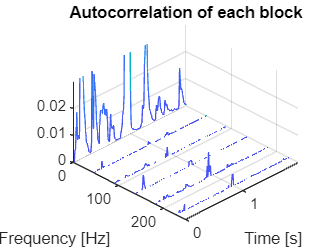

vSentenceIn = vSentenceIn(:,1);
vSentenceIn = resample(vSentenceIn,11025,iFs);
iFs = 11025;

% set parameters for blockwise processing
overlap = 0.5;
fBlockLength = 0.022;
fShift = fBlockLength*overlap;

[mOutput, iSamplesPerBlock, iSamplesPerShift, iNumBlocks, iSamplesMat] = output(vSentenceIn,iFs,fBlockLength,fShift);

% apply hann window on blockwise signal
mOutput_windowed = zeros(iSamplesPerBlock,iNumBlocks);
for i = 1:iNumBlocks
    mOutput_windowed(:,i) = hanning(size(mOutput,1)) .* mOutput(:,i);
end

% set filter order
iFilterOrder = 15;

% preallocate matrix for filter-coefficients per block
mLPC = zeros(iFilterOrder+1,iNumBlocks);

% initiate error signal 
vEn = zeros(iSamplesMat,1);

% initiate noise vector
vNoise = randn(iSamplesMat,1)/100;

% initiate pulse train with wanted frequency
iPulseFreq = 300;
vPulse = zeros(iSamplesMat,1);
vPulse(1:round(iFs/iPulseFreq):end) = 0.05;

% preallocate signal vectors
vSentenceOut = zeros(iSamplesMat,1);
vSentenceOutNoise = zeros(iSamplesMat,1);
vSentenceOutPulse = zeros(iSamplesMat,1);

for i = 1:iNumBlocks
    % index for current block
    idx_start = (i-1)*iSamplesPerShift+1;
    idx_end = idx_start+iSamplesPerBlock-1;

    % calculate filter coefficients of block and save in matrix
    vLPC_coeff = lpc(mOutput_windowed(:,i), iFilterOrder);
    mLPC(:,i) = vLPC_coeff;
    
    % obtain exitation signal from filtering original signal block
    vEn_block = filter(vLPC_coeff,1,mOutput_windowed(:,i));

    mEn(:,i) = filter(vLPC_coeff,1,mOutput_windowed(:,i));
    
    vEn(idx_start:idx_end,1) = filter(vLPC_coeff,1,mOutput_windowed(:,i));
    
    % synthesize all signals 
    vSentenceOut(idx_start:idx_end) = filter(1,vLPC_coeff,vEn_block);
    vSentenceOutNoise(idx_start:idx_end) = filter(1,vLPC_coeff,vNoise(idx_start:idx_end));
    vSentenceOutPulse(idx_start:idx_end) = filter(1,vLPC_coeff,vPulse(idx_start:idx_end));
    
    vSentenceOutNoise(idx_start:idx_end) = hanning(iSamplesPerBlock) .* vSentenceOutNoise(idx_start:idx_end); 
    vSentenceOutPulse(idx_start:idx_end) = hanning(iSamplesPerBlock) .* vSentenceOutPulse(idx_start:idx_end);

    % write per block for spectrograms
    [mSentenceOut, iSamplesPerBlock, iSamplesPerShift, iNumBlocks, iSamplesMat] = output(vSentenceOut, iFs, fBlockLength, fShift);
    [mSentenceOutNoise, iSamplesPerBlock, iSamplesPerShift, iNumBlocks, iSamplesMat] = output(vSentenceOutNoise, iFs, fBlockLength, fShift);
    [mSentenceOutPulse, iSamplesPerBlock, iSamplesPerShift, iNumBlocks, iSamplesMat] = output(vSentenceOutPulse, iFs, fBlockLength, fShift);
end


% calculate autocorrelation
for i = 1:iNumBlocks-1
    autocorrelation(:,i) = xcorr(mEn(:,i));
    %autocorrelation(:,i) = autocorrelation(:,i)/autocorrelation(242,i);
 end
zero_idx = ceil(size(autocorrelation,1)/2);

figure()
% freq_vec = 0:iSamplesPerBlock:iFs/(100*fBlockLength); % use linspace 
vTime = linspace(0,length(vEn)/iFs,iNumBlocks-1);
vFreq = linspace(0,iFs,iSamplesPerBlock);
waterfall(vTime,vFreq,autocorrelation(zero_idx:end,:))
view(135,45)
axis tight
set(gca,'XDir','reverse')
title('Autocorrelation of each block')
xlabel('Time [s]')
ylabel('Frequency [Hz]')
ylim([0 250])
zlim([0 0.03])
print('figures\waterfall_plot','-dpng')

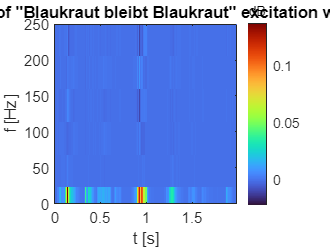


figure()
image(vTime,vFreq,autocorrelation(zero_idx:end,:), 'CDataMapping', 'scaled')
colormap('turbo')
hcb = colorbar();
hcb.Title.String = ('dB');
xlabel('t [s]')
ylabel('f [Hz]')
ylim([0 250])
title('Spectrogram of "Blaukraut bleibt Blaukraut" excitation with noise')
axis xy

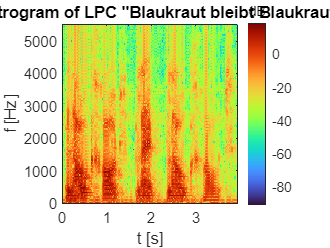


% save the three signals as audio 
audiowrite('sigout.wav',vSentenceOut,iFs);
audiowrite('sigoutnoise.wav',vSentenceOutNoise,iFs);
audiowrite('sigoutpulse.wav',vSentenceOutPulse,iFs);
%sound(vSentenceOutPulse,iFs)


% (C.V) spectrograms of:
% a) original sentence
mFFTSentenceOut = zeros(iSamplesPerBlock/2,iNumBlocks);
for i = 1:iNumBlocks
    vFFTSentenceOut = db(abs(fft(mSentenceOut(:,i))));
    mFFTSentenceOut(:,i) = vFFTSentenceOut(1:end/2);
end

vFreq = 0:iFs/length(vSentenceIn):iFs-iFs/length(vSentenceOut);
vTime = 0:fBlockLength:iNumBlocks*fBlockLength;

figure()
image(vTime,vFreq(1:round(end/2)),mFFTSentenceOut, 'CDataMapping', 'scaled')
colormap('turbo')
hcb = colorbar();
hcb.Title.String = ('dB');
xlabel('t [s]')
ylabel('f [Hz]')
title('Spectrogram of LPC "Blaukraut bleibt Blaukraut"')
axis xy

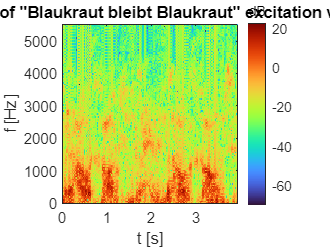


% b) sentence with noise excitation
mFFTSentenceOutNoise = zeros(ceil(iSamplesPerBlock/2),iNumBlocks);
for i = 1:iNumBlocks
    vFFTSentenceOutNoise = db(abs(fft(mSentenceOutNoise(:,i))));
    mFFTSentenceOutNoise(:,i) = vFFTSentenceOutNoise(1:end/2);
end

vFreq = 0:iFs/length(vSentenceIn):iFs-iFs/length(vSentenceOutNoise);
vTime = 0:fBlockLength:iNumBlocks*fBlockLength;

figure()
image(vTime,vFreq(1:round(end/2)),mFFTSentenceOutNoise, 'CDataMapping', 'scaled')
colormap('turbo')
hcb = colorbar();
hcb.Title.String = ('dB');
xlabel('t [s]')
ylabel('f [Hz]')
title('Spectrogram of "Blaukraut bleibt Blaukraut" excitation with noise')
axis xy

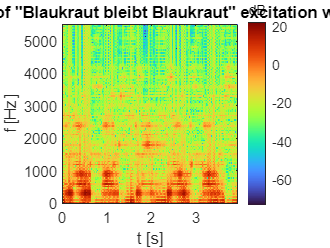


% c) sentence with pulse train excitation
mFFTSentenceOutPulse = zeros(iSamplesPerBlock/2,iNumBlocks);
for i = 1:iNumBlocks
    vFFTSentenceOutPulse = db(abs(fft(mSentenceOutPulse(:,i))));
    mFFTSentenceOutPulse(:,i) = vFFTSentenceOutPulse(1:end/2);
end

vFreq = 0:iFs/length(vSentenceIn):iFs-iFs/length(vSentenceOutPulse);
vTime = 0:fBlockLength:iNumBlocks*fBlockLength;

figure()
image(vTime,vFreq(1:round(end/2)),mFFTSentenceOutPulse, 'CDataMapping', 'scaled')
colormap('turbo')
hcb = colorbar();
hcb.Title.String = ('dB');
xlabel('t [s]')
ylabel('f [Hz]')
title('Spectrogram of "Blaukraut bleibt Blaukraut" excitation with pulses')
axis xy